clear all
clc

clear; clc; close all

width = 1.5 ; % Line thickness
lsize = 12 ; tsize = 14 ; legsize = 9 ; msize = 8 ; % Font size in plots, label, title, legend
set(0,'defaultAxesTickLabelInterpreter','latex');
set(0,'defaultTextInterpreter','latex'); set(0,'defaultLegendInterpreter','latex');

% COLOURS - MaTLAB defaults
blue = [0 0.4470 0.7410]; orange = [0.8500 0.3250 0.0980]; yellow = [0.9290 0.6940 0.1250];
purple = [0.4940 0.1840 0.5560]; green = [0.4660 0.6740 0.1880];
lblue = [0.3010 0.7450 0.9330];	red = [0.6350 0.0780 0.1840]; black = [0 0 0];

Machs = [1.2:0.1:2.5]

Machs =     1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000


Machs_rev =flip(Machs)

Machs_rev =     2.5000    2.4000    2.3000    2.2000    2.1000    2.0000    1.9000    1.8000    1.7000    1.6000    1.5000    1.4000    1.3000    1.2000


Machsqr = Machs.^2

Machsqr =     1.4400    1.6900    1.9600    2.2500    2.5600    2.8900    3.2400    3.6100    4.0000    4.4100    4.8400    5.2900    5.7600    6.2500


Machsqr_rev = flip(Machsqr)

Machsqr_rev =     6.2500    5.7600    5.2900    4.8400    4.4100    4.0000    3.6100    3.2400    2.8900    2.5600    2.2500    1.9600    1.6900    1.4400



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% We have 4 runs:
%     - Ma 1.2 --> 2.5 ramp10 hold25
%     - Ma 1.2 --> 2.5 ramp10 hold30
%     - Ma 1.2 --> 2.5 ramp10 hold40
% and a decceleration case
%     - Ma 2.5 --> 1.2 ramp10 hold25

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


## TIME SERIES CONSTRUCTION

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%     - Ma 1.2 --> 2.5 ramp10 hold25
Machs_all = reshape( cat( 1, [Machs], [Machs] ), 1, [] );
t_ramp = 10; t_hold = 25;
t_all = zeros(size(Machs_all));
for i=1:((2*length(Machs)))
    t_all(i)= floor(i/2)*t_hold+floor(i/2-1/2)*t_ramp;
end
t_all_r10h25 =t_all;
t_sampling=t_all(2:2:end);
% Time 1, Cm 2, Cd 3, Cl 4, Cl(f) 5, Cl(r) 6
t_lines_access_r10h25 = (t_sampling./1)

t_lines_access_r10h25 =     25    60    95   130   165   200   235   270   305   340   375   410   445   480


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%     - Ma 1.2 --> 2.5 ramp10 hold30
Machs_all = reshape( cat( 1, [Machs], [Machs] ), 1, [] );
t_ramp = 10; t_hold = 30;
t_all = zeros(size(Machs_all));
for i=1:((2*length(Machs)))
    t_all(i)= floor(i/2)*t_hold+floor(i/2-1/2)*t_ramp;
end
t_all_r10h30 =t_all;
t_sampling=t_all(2:2:end);
% Time 1, Cm 2, Cd 3, Cl 4, Cl(f) 5, Cl(r) 6
t_lines_access_r10h30 = (t_sampling./1)

t_lines_access_r10h30 =     30    70   110   150   190   230   270   310   350   390   430   470   510   550


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%     - Ma 1.2 --> 2.5 ramp10 hold40
Machs_all = reshape( cat( 1, [Machs], [Machs] ), 1, [] );
t_ramp = 10; t_hold = 40;
t_all = zeros(size(Machs_all));
for i=1:((2*length(Machs)))
    t_all(i)= floor(i/2)*t_hold+floor(i/2-1/2)*t_ramp;
end
t_all_r10h40 =t_all;
t_sampling=t_all(2:2:end);
% Time 1, Cm 2, Cd 3, Cl 4, Cl(f) 5, Cl(r) 6
t_lines_access_r10h40 = (t_sampling./1)

t_lines_access_r10h40 =     40    90   140   190   240   290   340   390   440   490   540   590   640   690


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%     - Ma 2.5 --> 1.2 ramp10 hold25
Machs_all_rev = reshape( cat( 1, [Machs_rev], [Machs_rev] ), 1, [] );
t_ramp = 10; t_hold = 25;
t_all = zeros(size(Machs_all));
for i=1:((2*length(Machs)))
    t_all(i)= floor(i/2)*t_hold+floor(i/2-1/2)*t_ramp;
end
t_all_r10h25d =t_all;
t_sampling=t_all(2:2:end);
% Time 1, Cm 2, Cd 3, Cl 4, Cl(f) 5, Cl(r) 6
t_lines_access_r10h25d = (t_sampling./1)

t_lines_access_r10h25d =     25    60    95   130   165   200   235   270   305   340   375   410   445   480


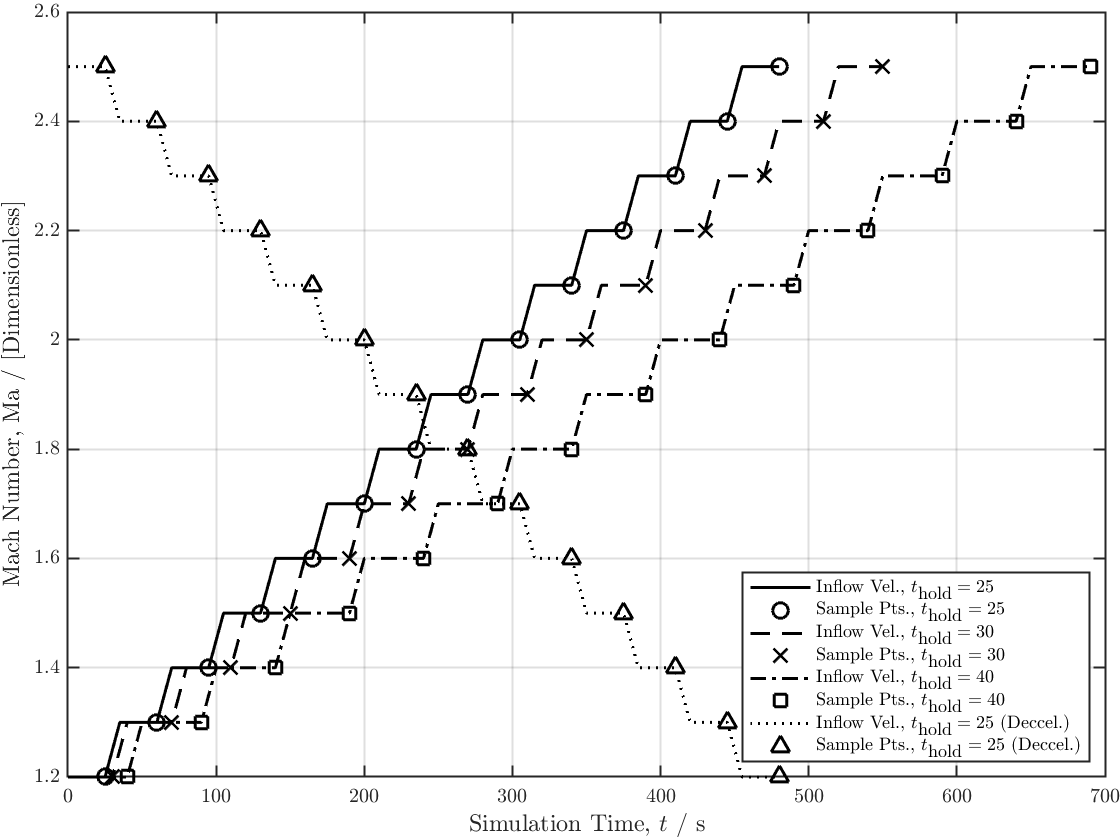

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure
plot(t_all_r10h25,Machs_all,'-','LineWidth',width,'MarkerSize',msize,'color',black)
hold on
plot(t_lines_access_r10h25,Machs,'o','LineWidth',width,'MarkerSize',msize,'color',black)

plot(t_all_r10h30,Machs_all,'--','LineWidth',width,'MarkerSize',msize,'color',black)
hold on
plot(t_lines_access_r10h30,Machs,'x','LineWidth',width,'MarkerSize',msize,'color',black)

plot(t_all_r10h40,Machs_all,'-.','LineWidth',width,'MarkerSize',msize,'color',black)
hold on
plot(t_lines_access_r10h40,Machs,'s','LineWidth',width,'MarkerSize',msize,'color',black)

plot(t_all_r10h25d,Machs_all_rev,':','LineWidth',width,'MarkerSize',msize,'color',black)
hold on
plot(t_lines_access_r10h25d,Machs_rev,'^','LineWidth',width,'MarkerSize',msize,'color',black)

grid on; box on; hold on
%title(["\textbf{OpenFOAM case inflow velocities and sampling times}","\textbf{Ramp} $t=10$\textbf{s}"],'FontSize',tsize)
ylabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
xlabel("Simulation Time, $t$ / s",'FontSize',lsize)
legend('Inflow Vel., $t_{\textrm{hold}}=25$', 'Sample Pts., $t_{\textrm{hold}}=25$',...
    'Inflow Vel., $t_{\textrm{hold}}=30$', 'Sample Pts., $t_{\textrm{hold}}=30$',...
    'Inflow Vel., $t_{\textrm{hold}}=40$', 'Sample Pts., $t_{\textrm{hold}}=40$',...
    'Inflow Vel., $t_{\textrm{hold}}=25$ (Deccel.)', 'Sample Pts., $t_{\textrm{hold}}=25$ (Deccel.)',...
    'Location',"southeast")
hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

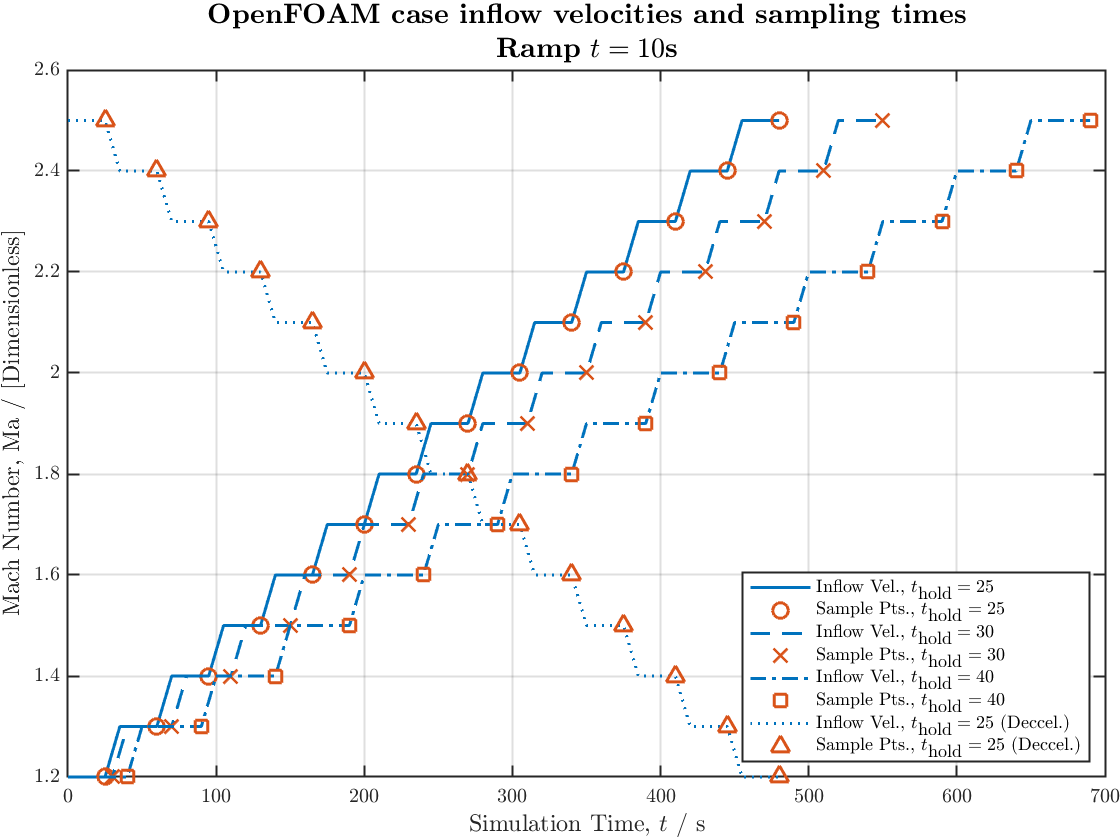


figure
plot(t_all_r10h25,Machs_all,'-','LineWidth',width,'MarkerSize',msize,'color',blue)
hold on
plot(t_lines_access_r10h25,Machs,'o','LineWidth',width,'MarkerSize',msize,'color',orange)

plot(t_all_r10h30,Machs_all,'--','LineWidth',width,'MarkerSize',msize,'color',blue)
hold on
plot(t_lines_access_r10h30,Machs,'x','LineWidth',width,'MarkerSize',msize,'color',orange)

plot(t_all_r10h40,Machs_all,'-.','LineWidth',width,'MarkerSize',msize,'color',blue)
hold on
plot(t_lines_access_r10h40,Machs,'s','LineWidth',width,'MarkerSize',msize,'color',orange)

plot(t_all_r10h25d,Machs_all_rev,':','LineWidth',width,'MarkerSize',msize,'color',blue)
hold on
plot(t_lines_access_r10h25d,Machs_rev,'^','LineWidth',width,'MarkerSize',msize,'color',orange)

grid on; box on; hold on
title(["\textbf{OpenFOAM case inflow velocities and sampling times}","\textbf{Ramp} $t=10$\textbf{s}"],'FontSize',tsize)
ylabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
xlabel("Simulation Time, $t$ / s",'FontSize',lsize)
legend('Inflow Vel., $t_{\textrm{hold}}=25$', 'Sample Pts., $t_{\textrm{hold}}=25$',...
    'Inflow Vel., $t_{\textrm{hold}}=30$', 'Sample Pts., $t_{\textrm{hold}}=30$',...
    'Inflow Vel., $t_{\textrm{hold}}=40$', 'Sample Pts., $t_{\textrm{hold}}=40$',...
    'Inflow Vel., $t_{\textrm{hold}}=25$ (Deccel.)', 'Sample Pts., $t_{\textrm{hold}}=25$ (Deccel.)',...
    'Location',"southeast")
hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

## DATA ACQUISITION

holdtime = [25,25,30,40];
simtime = [35344,36053,42446,61233]./3600

simtime =     9.8178   10.0147   11.7906   17.0092


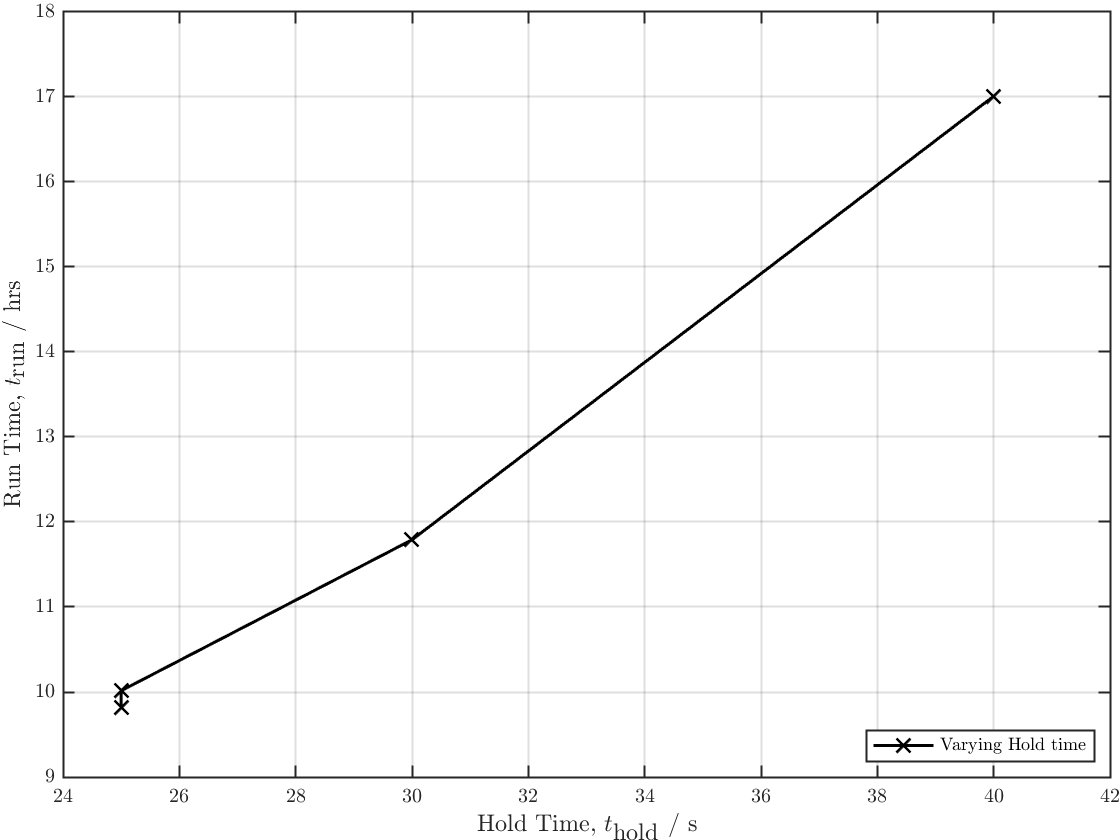


figure
plot(holdtime,simtime,'kx-','LineWidth',width,'MarkerSize',msize)
grid on; box on; hold on
%title("\textbf{Effect of varying the Hold time on total Simulation time}",'FontSize',tsize)
xlabel("Hold Time, $t_{\textrm{hold}}$ / s",'FontSize',lsize)
ylabel("Run Time, $t_{\textrm{run}}$ / hrs",'FontSize',lsize)
legend('Varying Hold time','Location',"southeast",'FontSize',legsize)
hold off
xlim([24 42])
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%     - Ma 1.2 --> 2.5 ramp10 hold30

        forces_r10h25 = importdata('forceCoeffs_Ma1.2-2.5_ramp10hold25.dat');
        %This is the part where we read off every so often line
        %% COEFF*MACH SQUARED
        momentM2 =   (forces_r10h25.data(t_lines_access_r10h25,2));
        cmM2_r10h25 = momentM2;
        dragM2 =   (forces_r10h25.data(t_lines_access_r10h25,3));
        cdM2_r10h25 = dragM2;
        liftM2 =   (forces_r10h25.data(t_lines_access_r10h25,4));
        clM2_r10h25 = liftM2;
        %% COEFFICIENTS
        moment =   (forces_r10h25.data(t_lines_access_r10h25,2));
        cm_r10h25 = moment./transpose(Machsqr);
        drag =   (forces_r10h25.data(t_lines_access_r10h25,3));
        cd_r10h25 = drag./transpose(Machsqr);
        lift =   (forces_r10h25.data(t_lines_access_r10h25,4));
        cl_r10h25 = lift./transpose(Machsqr);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%     - Ma 1.2 --> 2.5 ramp10 hold25

        forces_r10h30 = importdata('forceCoeffs_Ma1.2-2.5_ramp10hold30.dat');
        %This is the part where we read off every so often line
        %% COEFF*MACH SQUARED
        momentM2 =   (forces_r10h30.data(t_lines_access_r10h30,2));
        cmM2_r10h30 = momentM2;
        dragM2 =   (forces_r10h30.data(t_lines_access_r10h30,3));
        cdM2_r10h30 = dragM2;
        liftM2 =   (forces_r10h30.data(t_lines_access_r10h30,4));
        clM2_r10h30 = liftM2;
        %% COEFFICIENTS
        moment =   (forces_r10h30.data(t_lines_access_r10h30,2));
        cm_r10h30 = moment./transpose(Machsqr);
        drag =   (forces_r10h30.data(t_lines_access_r10h30,3));
        cd_r10h30 = drag./transpose(Machsqr);
        lift =   (forces_r10h30.data(t_lines_access_r10h30,4));
        cl_r10h30 = lift./transpose(Machsqr);
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%     - Ma 1.2 --> 2.5 ramp10 hold40

        forces_r10h40 = importdata('forceCoeffs_Ma1.2-2.5_ramp10hold40.dat');
        %This is the part where we read off every so often line
        %% COEFF*MACH SQUARED
        momentM2 =   (forces_r10h40.data(t_lines_access_r10h40,2));
        cmM2_r10h40 = momentM2;
        dragM2 =   (forces_r10h40.data(t_lines_access_r10h40,3));
        cdM2_r10h40 = dragM2;
        liftM2 =   (forces_r10h40.data(t_lines_access_r10h40,4));
        clM2_r10h40 = liftM2;
        %% COEFFICIENTS
        moment =   (forces_r10h40.data(t_lines_access_r10h40,2));
        cm_r10h40 = moment./transpose(Machsqr);
        drag =   (forces_r10h40.data(t_lines_access_r10h40,3));
        cd_r10h40 = drag./transpose(Machsqr);
        lift =   (forces_r10h40.data(t_lines_access_r10h40,4));
        cl_r10h40 = lift./transpose(Machsqr);
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% and a decceleration case
%     - Ma 2.5 --> 1.2 ramp10 hold25

        forces_r10h25d = importdata('forceCoeffs_Ma2.5-1.2_ramp10hold25.dat');
        %This is the part where we read off every so often line
        %% COEFF*MACH SQUARED
        momentM2 =   (forces_r10h25d.data(t_lines_access_r10h25d,2));
        cmM2_r10h25d = momentM2;
        dragM2 =   (forces_r10h25d.data(t_lines_access_r10h25d,3));
        cdM2_r10h25d = dragM2;
        liftM2 =   (forces_r10h25d.data(t_lines_access_r10h25d,4));
        clM2_r10h25d = liftM2;
        %% COEFFICIENTS
        moment =   (forces_r10h25d.data(t_lines_access_r10h25d,2));
        cm_r10h25d = moment./transpose(Machsqr_rev);
        drag =   (forces_r10h25d.data(t_lines_access_r10h25d,3));
        cd_r10h25d = drag./transpose(Machsqr_rev);
        lift =   (forces_r10h25d.data(t_lines_access_r10h25d,4));
        cl_r10h25d = lift./transpose(Machsqr_rev);

## PLOTTING

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Kusunose_review_fig25_busemandeccel_machs=[0.5,0.55,0.6,0.65,0.7,0.75,0.80,0.85,0.90,1,1.1,1.2,1.3,1.4,1.5,1.6,1.631578947,1.636363636,1.65,1.7,1.8,1.9,2,2.1,2.2,2.5];
Kusunose_review_fig25_busemandeccel_cd=[0.004031311,0.023757339,0.072367906,0.106888454,0.131545988,0.148219178,0.147749511,0.138121331,0.13037182,0.11816047,0.110176125,0.104305284,0.100547945,0.097495108,0.095146771,0.093268102,0.092798434,0.004500978,0.003796477,0.002152642,0.003561644,0.00590998,0.008023483,0.009902153,0.011076321,0.014833659];
Kusunose_review_fig25_busemanaccel_machs=[1.626794258,1.7,1.8,1.9,2,2.1,2.138755981,2.157894737,2.17,2.177033493,2.2];
Kusunose_review_fig25_busemanaccel_cd=[0.092798434,0.091624266,0.090215264,0.089041096,0.087632094,0.085988258,0.085283757,0.08481409,0.084344423,0.011076321,0.011311155];

Hu_et_al_fig16_buseman_machs=[0.3,0.4,0.5,0.6,0.7,0.8,0.9,1,1.1,1.2,1.3,1.4,1.5,1.6,1.61,1.633744856,1.652263374,1.7,1.8,1.9,2,2.1,2.2,2.3,2.4,2.5,2.6,2.7,2.8,2.9,3,3.1,3.2,3.3];
Hu_et_al_fig16_buseman_cd=[0.004453441,0.004453441,0.007125506,0.063724696,0.129554656,0.14048583,0.124574899,0.113522267,0.105020243,0.098947368,0.095668016,0.092753036,0.090566802,0.088744939,0.006153846,0.005060729,0.004331984,0.003481781,0.003846154,0.005789474,0.007611336,0.009554656,0.011133603,0.012469636,0.013805668,0.01465587,0.01562753,0.015870445,0.015263158,0.01465587,0.01417004,0.013684211,0.013076923,0.012712551];
%busemann accel
Hu_et_al_fig16_buseman_accel_machs=[1.596707819,1.697530864,1.802469136,1.899176955,2,2.030864198,2.053497942,2.082304527,2.100823045,2.102880658];
Hu_et_al_fig16_buseman_accel_cd=[0.088744939,0.087165992,0.085708502,0.084008097,0.082307692,0.081578947,0.08097166,0.08048583,0.080121457,0.009554656];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% DRAG
cd_r10h25

cd_r10h25 =     0.1064
    0.1017
    0.0986
    0.0967
    0.0944
    0.0929
    0.0915
    0.0897
    0.0883
    0.0853


cd_r10h30

cd_r10h30 =     0.1061
    0.1017
    0.0986
    0.0967
    0.0944
    0.0929
    0.0915
    0.0897
    0.0883
    0.0853


cd_r10h40

cd_r10h40 =     0.1059
    0.1014
    0.0987
    0.0967
    0.0944
    0.0929
    0.0915
    0.0897
    0.0883
    0.0853


cd_r10h25d

cd_r10h25d =     0.0148
    0.0138
    0.0126
    0.0113
    0.0098
    0.0079
    0.0058
    0.0037
    0.0022
    0.0161


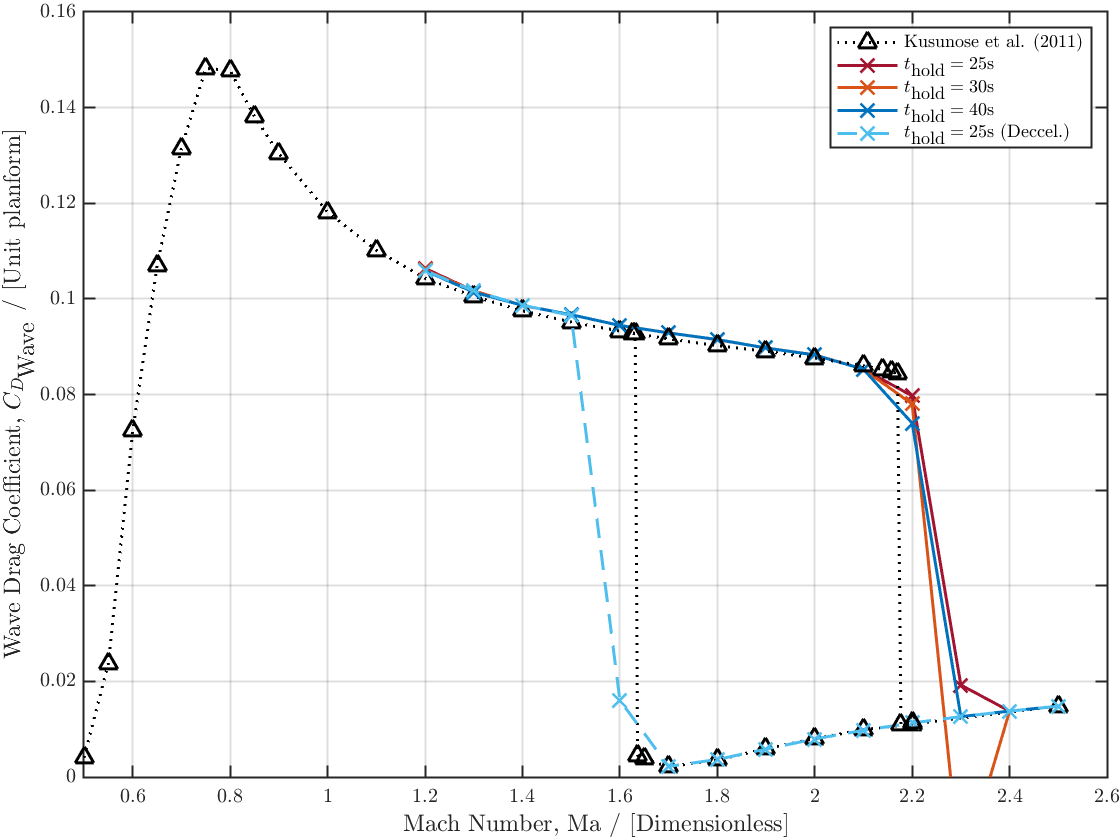


figure
hold on
plot(Kusunose_review_fig25_busemandeccel_machs,Kusunose_review_fig25_busemandeccel_cd,':^',"LineWidth",width,'MarkerSize',msize,'color',black)
%
plot(Machs,cd_r10h25,'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",red)
plot(Machs,cd_r10h30,'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",orange)
plot(Machs,cd_r10h40,'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",blue)
plot(Machs_rev,cd_r10h25d,'x--',"LineWidth",1.5,"MarkerSize",msize,"Color",lblue)
%
plot(Kusunose_review_fig25_busemanaccel_machs,Kusunose_review_fig25_busemanaccel_cd,':^',"LineWidth",width,'MarkerSize',msize,'color',black)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Wave Drag Coefficient, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
%title(["\textbf{Output drag coefficients for varying run Hold times}","\textbf{Ramp} $t=10$\textbf{s}"],'FontSize',tsize)
legend("Kusunose et al. (2011)",...%"Busemann, Hu \textit{et al.}","Busemann (Accel.), Hu \textit{et al.}",...
    "$t_{\textrm{hold}}=25 \textrm{s}$","$t_{\textrm{hold}}=30 \textrm{s}$","$t_{\textrm{hold}}=40 \textrm{s}$","$t_{\textrm{hold}}=25 \textrm{s}$ (Deccel.)",...
    "Location","northeast","NumColumns",1,'FontSize',legsize)
ylim([0,0.16]);
xlim([0.5,2.6]);
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

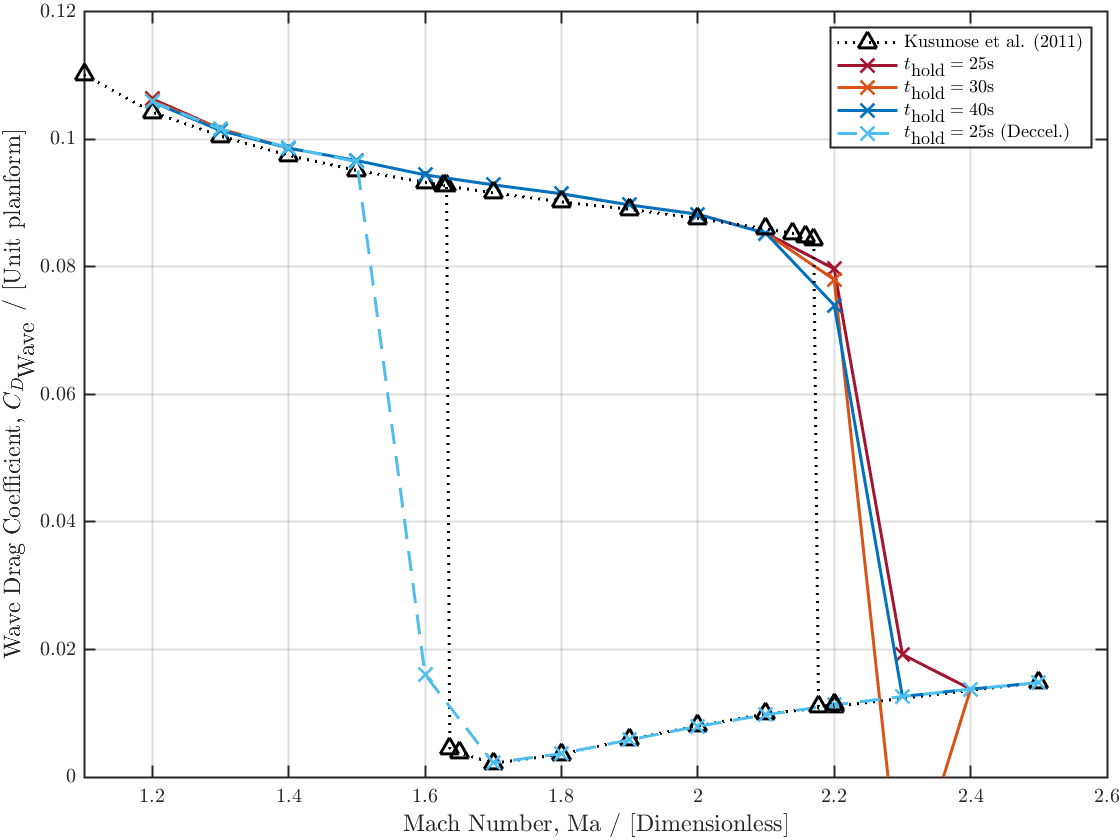


%% DRAG ZOOM

figure
hold on
plot(Kusunose_review_fig25_busemandeccel_machs,Kusunose_review_fig25_busemandeccel_cd,'^:',"LineWidth",width,'MarkerSize',msize,'color',black)
%plot(Hu_et_al_fig16_buseman_machs,Hu_et_al_fig16_buseman_cd,'.:',"LineWidth",width,'color',green,'MarkerSize',msize)
%plot(Hu_et_al_fig16_buseman_accel_machs,Hu_et_al_fig16_buseman_accel_cd,'.:',"LineWidth",width,'color',purple,'MarkerSize',msize)
%
plot(Machs,cd_r10h25,'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",red)
plot(Machs,cd_r10h30,'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",orange)
plot(Machs,cd_r10h40,'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",blue)
plot(Machs_rev,cd_r10h25d,'x--',"LineWidth",1.5,"MarkerSize",msize,"Color",lblue)
%
plot(Kusunose_review_fig25_busemanaccel_machs,Kusunose_review_fig25_busemanaccel_cd,'^:',"LineWidth",width,'MarkerSize',msize,'color',black)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Wave Drag Coefficient, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
%title(["\textbf{Output drag coefficients for varying run Hold times}","\textbf{Ramp} $t=10$\textbf{s}"],'FontSize',tsize)
legend("Kusunose et al. (2011)",...%"Busemann, Hu \textit{et al.}","Busemann (Accel.), Hu \textit{et al.}",...
    "$t_{\textrm{hold}}=25 \textrm{s}$","$t_{\textrm{hold}}=30 \textrm{s}$","$t_{\textrm{hold}}=40 \textrm{s}$","$t_{\textrm{hold}}=25 \textrm{s}$ (Deccel.)",...
    "Location","northeast","NumColumns",1,'FontSize',legsize)
ylim([0,0.12]);
xlim([1.1,2.6]);
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

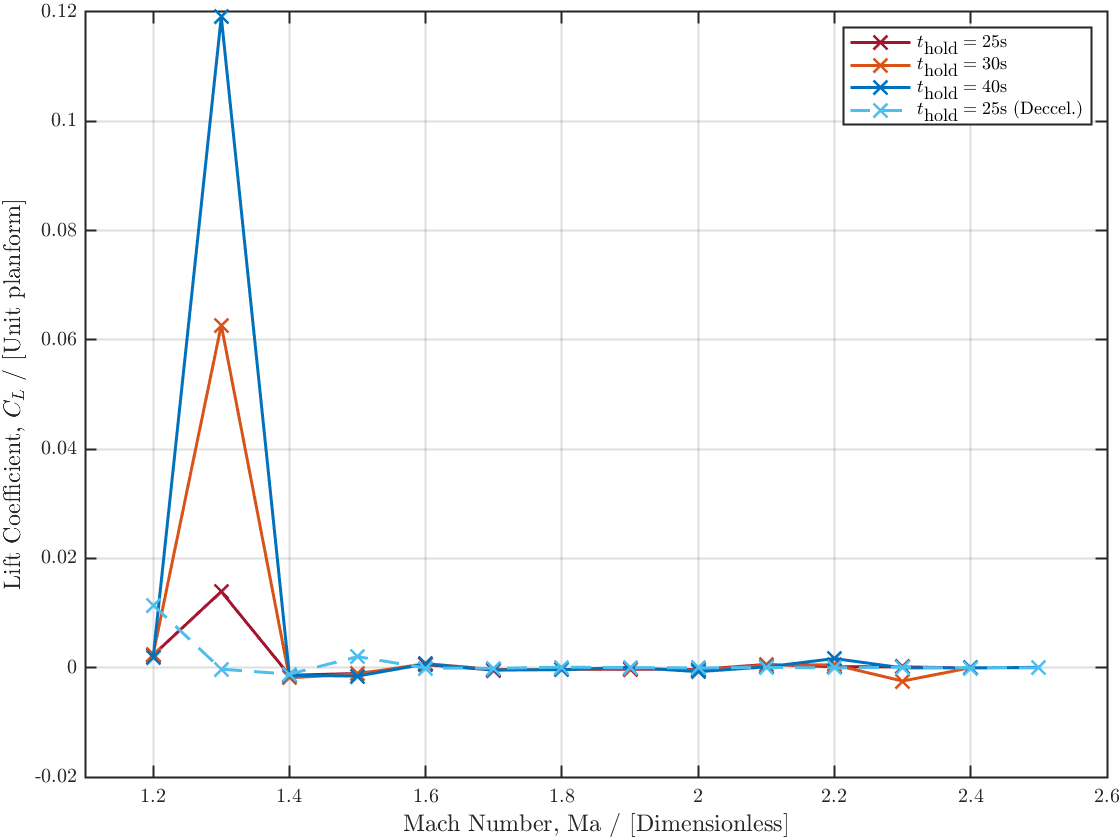


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% LIFT - SHOULD BE ZERO

figure
hold on
%
plot(Machs,cl_r10h25,'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",red)
plot(Machs,cl_r10h30,'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",orange)
plot(Machs,cl_r10h40,'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",blue)
plot(Machs_rev,cl_r10h25d,'x--',"LineWidth",1.5,"MarkerSize",msize,"Color",lblue)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Lift Coefficient, $C_{L}$ / [Unit planform]",'FontSize',lsize)
%title("\textbf{Output Lift coefficients for varying run Hold times}",'FontSize',tsize)
legend("$t_{\textrm{hold}}=25 \textrm{s}$","$t_{\textrm{hold}}=30 \textrm{s}$","$t_{\textrm{hold}}=40 \textrm{s}$","$t_{\textrm{hold}}=25 \textrm{s}$ (Deccel.)",...
    "Location","northeast","NumColumns",1,'FontSize',legsize)
%ylim([0,0.16]);
xlim([1.1,2.6]);
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

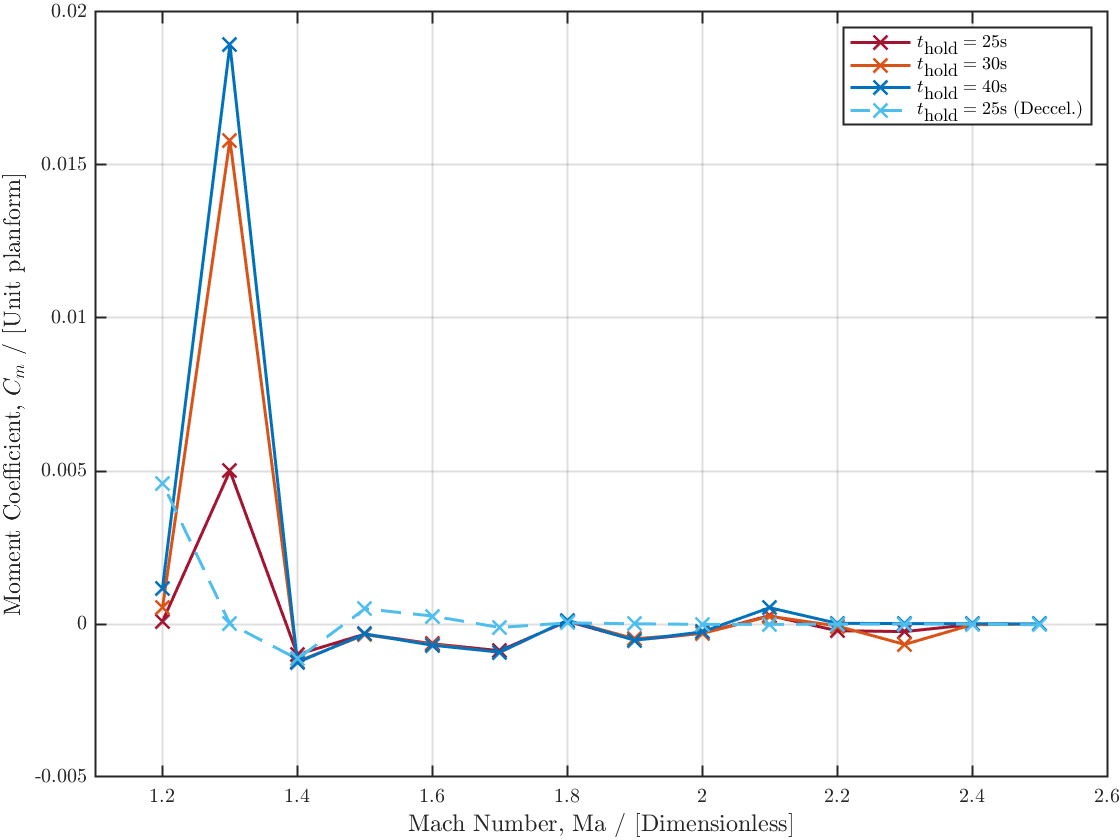


%% MOMENT

figure
hold on
%
plot(Machs,cm_r10h25,'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",red)
plot(Machs,cm_r10h30,'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",orange)
plot(Machs,cm_r10h40,'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",blue)
plot(Machs_rev,cm_r10h25d,'x--',"LineWidth",1.5,"MarkerSize",msize,"Color",lblue)
xlabel("Mach Number, $\textrm{Ma}$ / [Dimensionless]",'FontSize',lsize)
ylabel("Moment Coefficient, $C_{m}$ / [Unit planform]",'FontSize',lsize)
ax = gca;
ax.YRuler.Exponent = 0;
%title("\textbf{Output Moment coefficients for varying run Hold times}",'FontSize',tsize)
legend("$t_{\textrm{hold}}=25 \textrm{s}$","$t_{\textrm{hold}}=30 \textrm{s}$","$t_{\textrm{hold}}=40 \textrm{s}$","$t_{\textrm{hold}}=25 \textrm{s}$ (Deccel.)",...
    "Location","northeast","NumColumns",1,'FontSize',legsize)
%ylim([0,0.16]);
xlim([1.1,2.6]);
box on; grid on; hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;